clear all;

## Onset Conditions

dimension:

N=10;
% correlation paramter:
eta=1;% 1 is symmetric
% amplitude
JAmp=1;
% Sparsity of J
Mdensity=0;
% Tot time 
tot_time=20000;
% Delta t:
Dt=0.1;
% Temperature: Increase it!!!
T=0.1;
% Initialise
J=zeros(N,N);
%x=zeros(N,N_tot);
% ICs
var_ICs_X=0.01;
x(:,1)=var_ICs_X*randn(N,1);
M=sum(x(:,1).^2);
% Fix the constraint sum x^2=N for all t
x(:,1)=x(:,1)*sqrt(N)/sqrt(M);

## Generate Random Matrix:

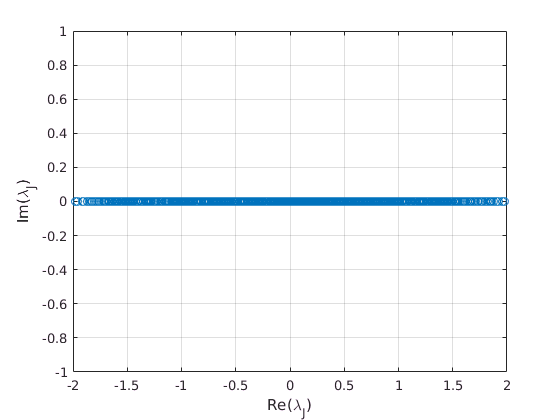

if eta==0
    J=JAmp/sqrt(N)*randn(N);   
 % In case you want sparse:  
 % J=JAmp/sqrt(n)*sprandn(n,n,Mdensity);
J=J-diag(diag(J));
else
    a=sqrt(1-eta^2);
    a=sqrt((1-a)/2);
    b=eta/(2*a);    
    J=JAmp/sqrt(N)*randn(N);    
 % In case you want sparse:  
 % J=JAmp/sqrt(n)*sprandn(n,n,Mdensity);
    J=a*J+b*J';
    J=J-diag(diag(J));
end;
figure;
plot(real(eig(J)),imag(eig(J)),'o');hold on;grid on;
xlabel('Re(\lambda_J)');
ylabel('Im(\lambda_J)')

%hold on;

## Run Dynamics

N_iter=tot_time/Dt;
for i=2:N_iter
    z=randn(N,1)*sqrt(2*Dt*T);
    f=Dt*J*x(:,i-1)+z;
    x_norm=N;
    B=1+x(:,i-1)'*f/x_norm;
    D=(f'*(2*x(:,i-1)+f))/x_norm;
    mu=(B-sqrt(B^2-D));%this is the mu * Dt term
    x(:,i)=(1-mu)*x(:,i-1)+f;
end

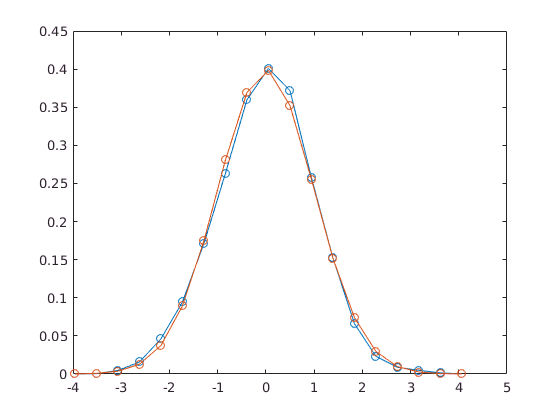

figure()
%histogram of position for one spin
bin_edge=linspace(min(x(:)),max(x(:)),20);
H=0;
for i=1:size(x,1)
    [h,b]=histcounts(x(:,i),bin_edge);
    H=H+h;
end
normalisation=sum(H)*(bin_edge(2)-bin_edge(1));
plot((bin_edge(1:end-1)+bin_edge(2:end))/2,H/normalisation,'-o')
hold on
spins=(bin_edge(1:end-1)+bin_edge(2:end))/2;
prob=exp(-spins.^2/2);
plot(spins,prob/sum(prob)/(bin_edge(2)-bin_edge(1)),'-o')

I compute  $\langle x_t x_{t'}\rangle=\frac{1}{N}\sum_{i=1}^N x_{i,t}x_{i,t'}$ i.e. I average over the different realisation of the spins.

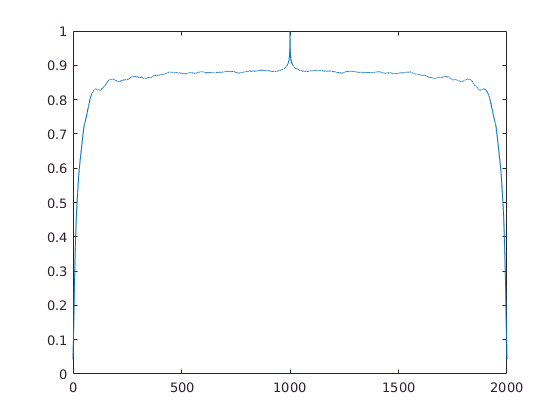

figure()
corr=0;
%hold on
for i=1:size(x,1)
    %plot(xcorr(x(i,:),'unbiased'))
    corr=corr+xcorr(x(i,:),'unbiased');
end
corr=corr/N;
%hold off
figure()
plot((1:length(corr))*Dt,corr)

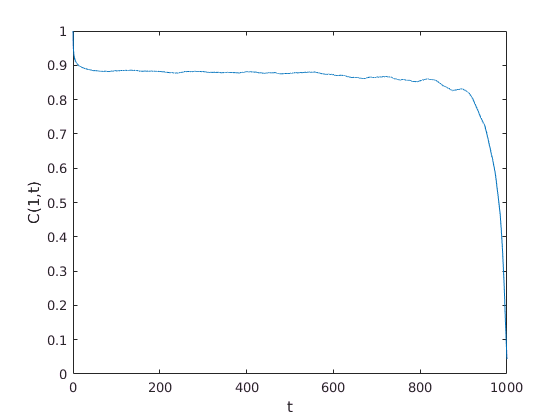

c=corr((end+1)/2:end);
plot((1:length(c))*Dt,c)
xlabel('t')
ylabel('C(1,t)')

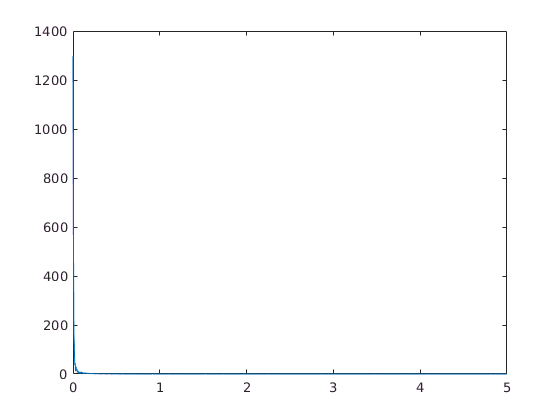


% Fourier transfrorm of correlation function
P2=abs(fft(corr));
P1=P2(1:(end+1)/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = 1/Dt*linspace(0,0.5,N_iter);
plot(f,P1(1:end-1))